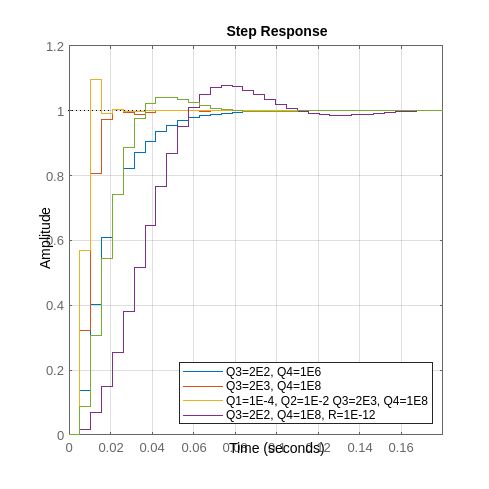

clear; clc;
cd ~/git/hardDiskControl/discreteTimeControl/
load ../data/sysDT.mat
load ../data/Gz.mat
load ../data/ppPoles.mat

riseTime = 0.052333; %seconds
Ts = riseTime/10;

figure('Position',[0 0 1000 1000]); clf; hold on;

Q = diag([0 0 2E2 1E6]);
R = [0];
[X,Klqr,L] = idare(sysDT.A,sysDT.B,Q,R);
sysLQR = ss(sysDT.A-sysDT.B*Klqr,sysDT.B,sysDT.C,sysDT.D,Ts);
sysLQR.B = sysLQR.B*dcgain(sysLQR)^-1;

step(sysLQR)

Q = diag([0 0 2E3 1E8]);
R = [0];
[X,Klqr,L] = idare(sysDT.A,sysDT.B,Q,R);
sysLQR = ss(sysDT.A-sysDT.B*Klqr,sysDT.B,sysDT.C,sysDT.D,Ts);
sysLQR.B = sysLQR.B*dcgain(sysLQR)^-1;

step(sysLQR)

Q = diag([0 0 2E2 1E8]);
R = [0];
[X,Klqr,L] = idare(sysDT.A,sysDT.B,Q,R);
sysLQR = ss(sysDT.A-sysDT.B*Klqr,sysDT.B,sysDT.C,sysDT.D,Ts);
sysLQR.B = sysLQR.B*dcgain(sysLQR)^-1;

step(sysLQR)

Q = diag([1E-4 1E-4 2E3 1E8]);
R = [0];
[X,Klqr,L] = idare(sysDT.A,sysDT.B,Q,R);
sysLQR = ss(sysDT.A-sysDT.B*Klqr,sysDT.B,sysDT.C,sysDT.D,Ts);
sysLQR.B = sysLQR.B*dcgain(sysLQR)^-1;

step(sysLQR)

Q = diag([0 0 2E2 1E8]);
R = [1E-12];
[X,Klqr,L] = idare(sysDT.A,sysDT.B,Q,R);
sysLQR = ss(sysDT.A-sysDT.B*Klqr,sysDT.B,sysDT.C,sysDT.D,Ts);
sysLQR.B = sysLQR.B*dcgain(sysLQR)^-1;

step(sysLQR)
legend("Q3=2E2, Q4=1E6","Q3=2E3, Q4=1E8","Q1=1E-4, Q2=1E-2 Q3=2E3, Q4=1E8","Q3=2E2, Q4=1E8, R=1E-12","Location","southeast")

grid on;